## State feedback for the gantry crane model

% Load your own arx models as returned by the arx function, or use the
% models identified by yours truly

load crane_sysid_result.mat % Loads arx441, arx661

% Choose the model to use for the design
mdl = arx661;
%mdl = arx441;

[num, den, h] = tfdata(mdl); % Get the polynomials and the sampling period
a = den{1};
b = num{1};
n = length(a)-1; % Model order



## Design


% Using controllable canonical form
Phi = [-a(2:end); eye(n-1), zeros(n-1,1)]

Phi =     3.4798   -5.1686    4.5616   -3.0261    1.6437   -0.4904
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0


Gamma = [1;zeros(n-1,1)]

Gamma =      1
     0
     0
     0
     0
     0


C = b(2:end)

C = 	1.0e+-6 *

    0.0209    0.2615    0.2765    0.1333    0.0823   -0.0187


D = 0;

sys = ss(Phi, Gamma, C, D, h)

sys =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1     3.48   -5.169    4.562   -3.026    1.644  -0.4904
   x2        1        0        0        0        0        0
   x3        0        1        0        0        0        0
   x4        0        0        1        0        0        0
   x5        0        0        0        1        0        0
   x6        0        0        0        0        1        0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
 
  C = 
               x1          x2          x3          x4          x5          x6
   y1   2.093e-08   2.615e-07   2.765e-07   1.333e-07   8.234e-08  -1.871e-08
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.



[ pole(sys), pole(mdl)] % Check that poles are correct. The order doesn not matter

ans =   -0.0822 + 0.7031i  -0.0822 + 0.7031i
  -0.0822 - 0.7031i  -0.0822 - 0.7031i
   0.8211 + 0.5500i   0.8211 + 0.5500i
   0.8211 - 0.5500i   0.8211 - 0.5500i
   1.0010 + 0.0067i   1.0010 + 0.0067i
   1.0010 - 0.0067i   1.0010 - 0.0067i



% Controllability and observability
Ctr = ctrb(Phi, Gamma);
fprintf('Controllable = %d\n', rank(Ctr) == n);

Controllable = 1


Obs = obsv(Phi, C);
fprintf('Observable = %d\n', rank(Obs) == n);

Observable = 1




% Desired poles. Make some smart choices based on the poles of the
% plant. Let the closed-loop system have the same oscillatory modes
% (complex poles) as the plant, but better damped (as necessary).
figure()
pzmap(mdl)

if n==4
    pd = [];
elseif n==6
    pd = [];
end


% State feedback gain
Lv = place(Phi, Gamma, pd);
%Lv = acker(Phi, Gamma, pd); % Only use acker if you have repeated poles

dcgn = C*( (eye(n) - (Phi-Gamma*Lv))\Gamma); % The DC gain
l0 = 1/dcgn;

% Observer poles. These should be faster (closer to the origin) than
% the closed-loop poles.
d = 2;
po = pd/d;

% Observer gain
K = place(Phi', C', po)';


% The closed-loop system. This consists of the states of the process model
% as well as the states of the observer.
% An output disturbance is included as an input in addition to the 
% reference signal
Phi_c = [Phi,  - Gamma*Lv
    K*C, Phi-Gamma*Lv-K*C];
Gamma_c = [l0*Gamma, zeros(n,1)
            l0*Gamma, K];
C_c = [C, zeros(1,n)];
sys_c = ss(Phi_c, Gamma_c, C_c, [D, 1], h)

sys_c =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11
   x1       3.48    -5.169     4.562    -3.026     1.644   -0.4904   -0.4898     1.226    -1.271    0.8804   -0.5627
   x2          1         0         0         0         0         0         0         0         0         0         0
   x3          0         1         0         0         0         0         0         0         0         0         0
   x4          0         0         1         0         0         0         0         0         0         0         0
   x5          0         0         0         1         0         0         0         0         0         0         0
   x6          0         0         0         0         1         0         0         0         0         0         0
   x7     0.0799    0.9983     1.055    0.5088    0.3143  -0.07141      2.91    -4.941     2.235    -2.655    0.7667
   x8    0.05557    0.6943    0.7341    0.3539 

## Check step responses and frequency properties

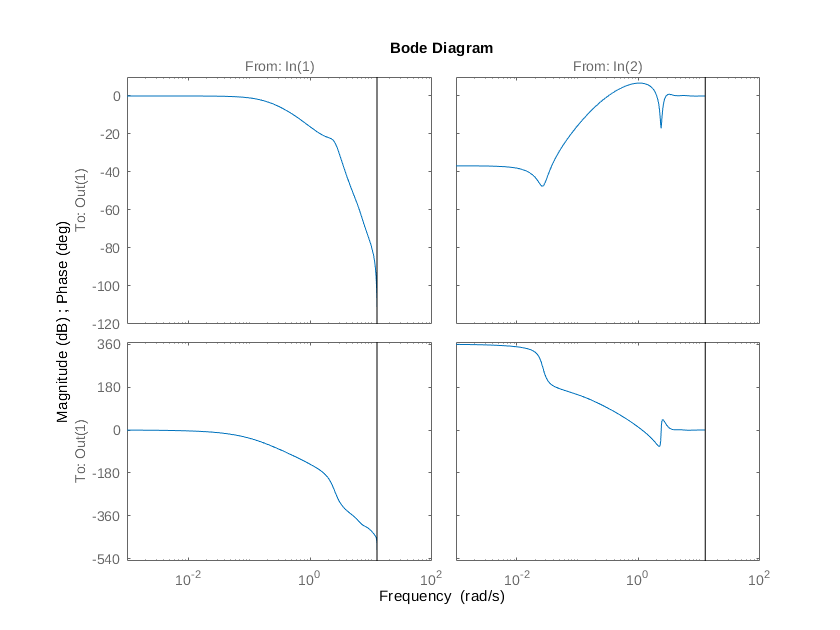

figure()
bode(sys_c)

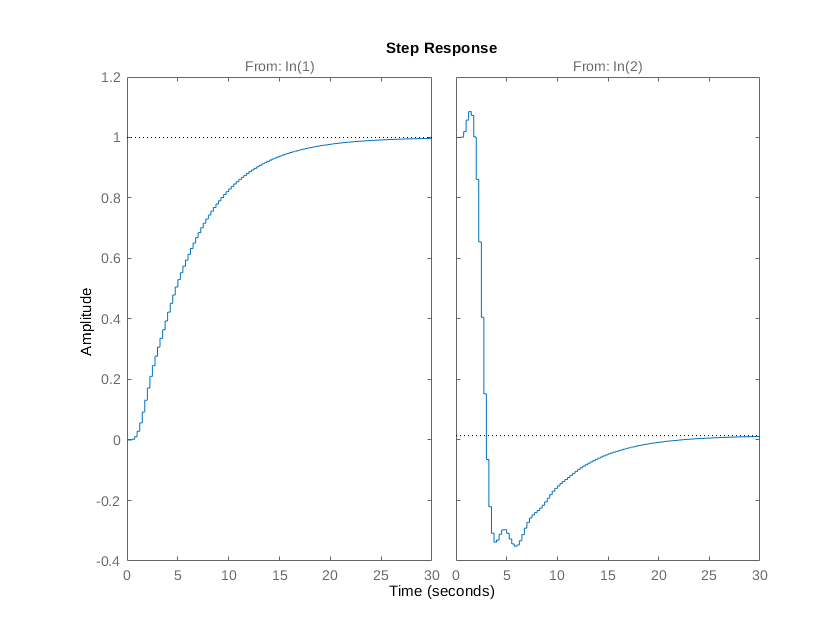

figure()
step(sys_c)